**1. Frequency domain filtering.** Do the following for 2 images of your choice **(10 points each for all sub-parts = 30 points total)**

- Apply low pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Apply high pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Add noise to your images. Does spatial domain filtering (median filtering, spatial domain gauss filter, etc.) work better to remove this noise or frequency domain filtering?

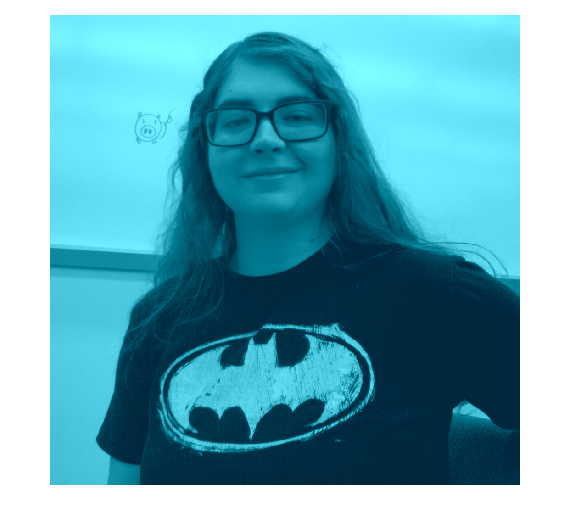

miranda = imread('../images/IMAGE012.jpg');
miranda = miranda(:,301:1500,:);
imshow(miranda);

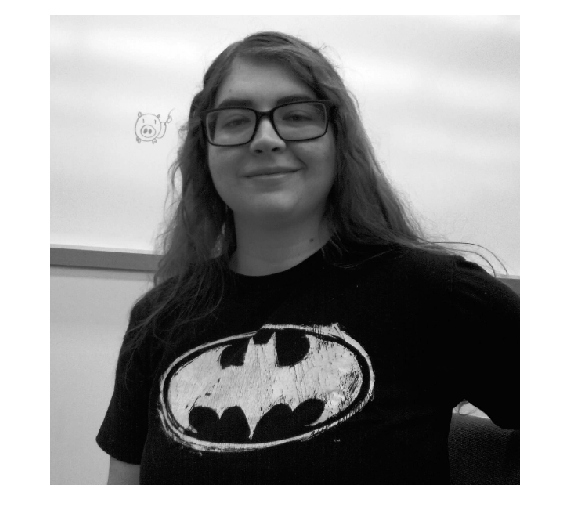

mg = im2gray(miranda);
imshow(mg,[])

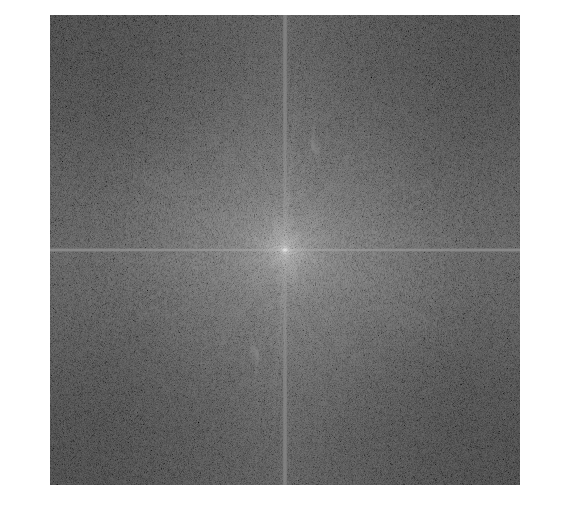


Y = fft2(mg,1200, 1200);
Y1 = abs(Y);
Y2 = log(abs(Y));
Y3 = log(abs(fftshift(Y)));
imshow(Y3, []);


% img_filt = ifft2(ifftshift(exp(Y4)));
% imshow(img_filt,[])

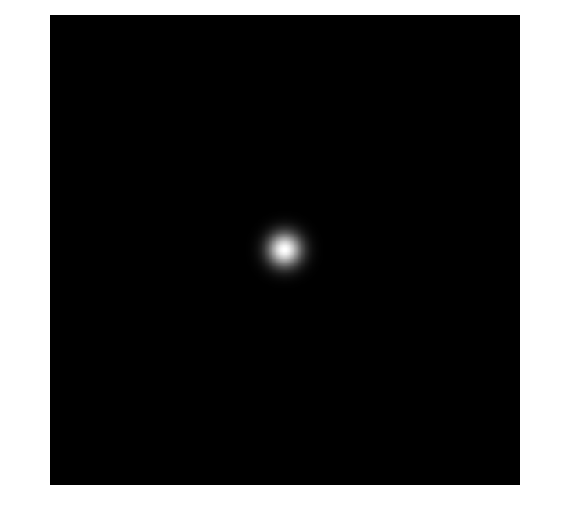

s = 1200;
sigma = 50;
gauss_2d = zeros(s);
for i = 1:s
    for j = 1:s
        gauss_2d(i, j) = ( ...
            1/(2*3.14*sigma^2) * ...
            exp(-1/2*((i-600)^2+(j-600)^2)/sigma^2) ...
            );
    end
end
imshow(gauss_2d,[])

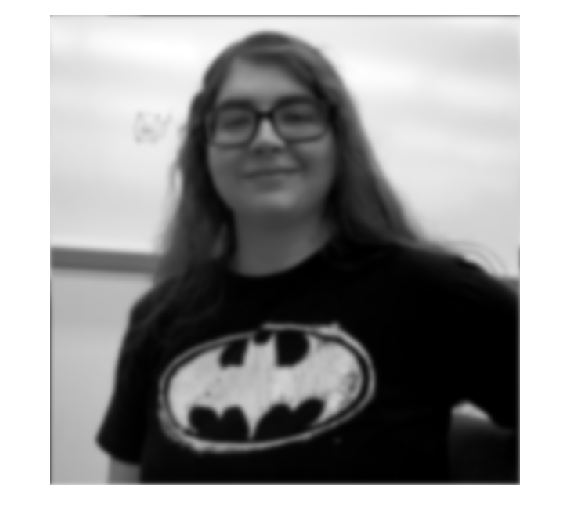

filtered = Y .* ifftshift(gauss_2d);
img_filt = ifft2(filtered);
imshow(img_filt,[])

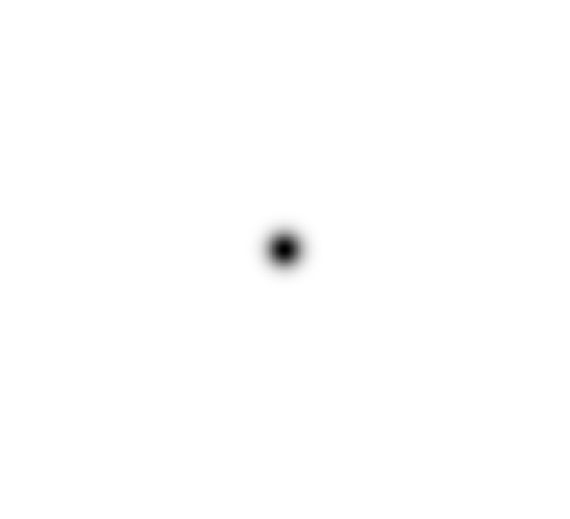


mid = (max(gauss_2d(:)) - min(gauss_2d(:)))/2;
gauss_I = -1*(gauss_2d - mid)+mid;
imshow(gauss_I, [])

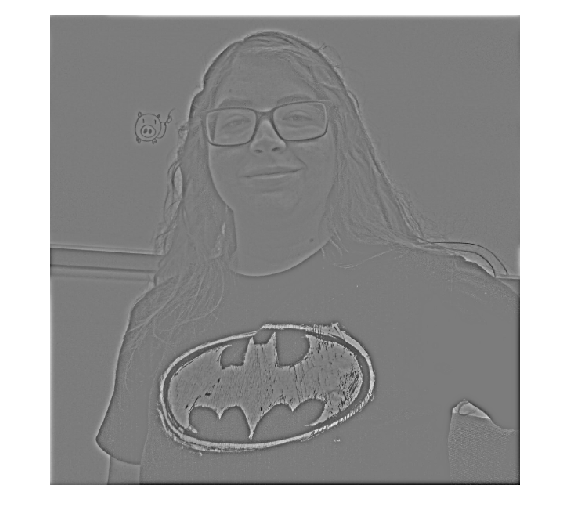

filtered = Y .* ifftshift(gauss_I);
img_filt = ifft2(filtered);
imshow(img_filt,[])



computer = imread('../images/IMAGE001.jpg')
computer = computer(:,51:530,:);
imshow(computer);
cg = im2gray(computer);

** 2. Deconvolution and** **Deblurring.** MATLAB and other programming platforms allow you to do a blind deconvolution or use some pre-designed functions to achieve deblurring. Try out the given sample code [trydeconv.m](https://canvas.olin.edu/courses/819/files/186973?wrap=1) on some of your images. 

What are the pros and cons of these pre-designed functions? Pre-designed functions estimate the blurring kernel for you. Research and explain any two methods of estimating a deblurring kernel without using pre-designed functions? You can use any material available to do your research – youtube videos, research papers, tutorials – whatever your group chooses. **(30 points).** (might be helpful to review [MATLAB summary of blind deconvolutionLinks to an external site.](https://www.mathworks.com/help/images/ref/deconvblind.html)).

**3. Histogram equalization.** Use histogram equalization as an image enhancement technique on two images of your choice. If you used inbuilt functions (e.g. histeq in MATLAB, or cv2.equalizeHist() in OpenCV), did you see any limitations of these inbuilt functions? If yes, what are they? **(10 points). **(sample histogram equalization code: [imenhance.m](https://canvas.olin.edu/courses/819/files/186985?wrap=1)

**4. Some more filtering.** You are provided with a code ‘[Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868?wrap=1). It implements 3 types of low pass filters in frequency domain – ideal, butterworth and gaussian. Run this code for an image of your choice. Comment on the effects of these filters in your image. Feel free to play around with parameters and those changes to your comments. **(10 points).**

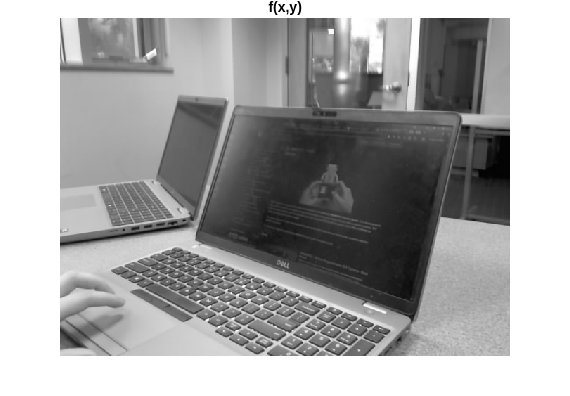

clc
clear all
clf
%%

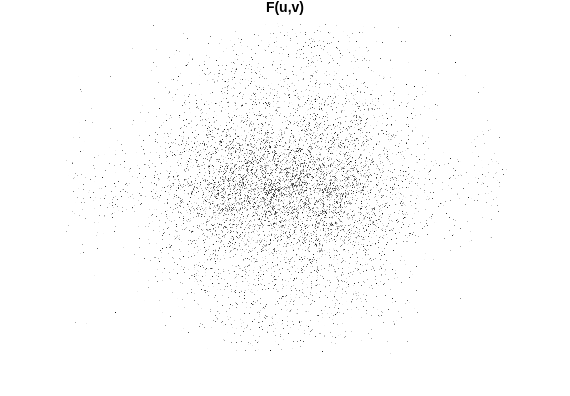

img = imread('../images/IMAGE001.jpg');
gimg=rgb2gray(img);
imshow(gimg)
title('f(x,y)')
%% Ideal low pass
P=size(gimg);
M=P(1);N=P(2);

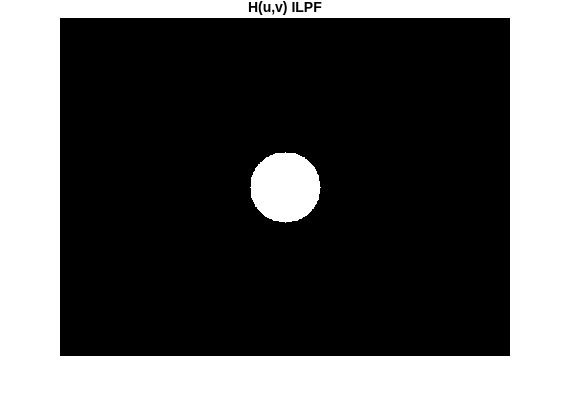

F=fft2(gimg,M,N);
%imshow(uint8(abs(fftshift(F))));
imshow(uint8(abs((F))));
title('F(u,v)')
u0=50; %remove freq greater than u0
u=0:(M-1);
v=0:(N-1);
idx=find(u>M/2);
u(idx)=u(idx)-M;
idy=find(v>N/2);
v(idy)=v(idy)-N;
[V,U]=meshgrid(v,u);
D=sqrt(U.^2+V.^2);

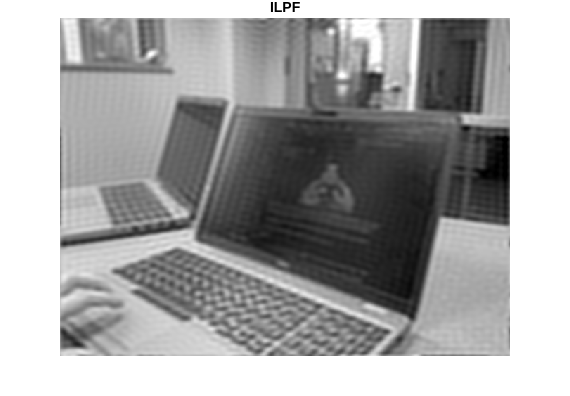

H=double(D<=u0);
% display
imshow(abs(fftshift(H)),[]);
title('H(u,v) ILPF')

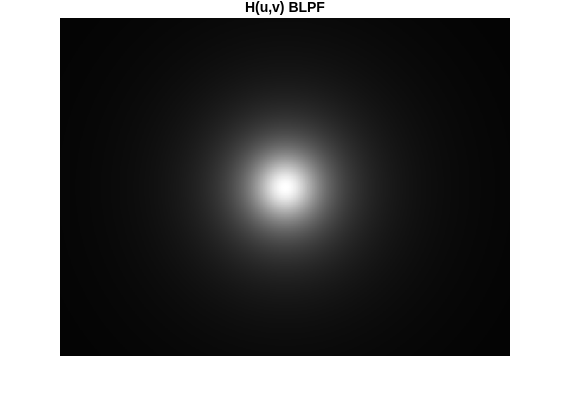

G=H.*F;
gideal=(ifft2(G));
imshow(uint8(gideal))
title('ILPF')
%% Butterworth low pass

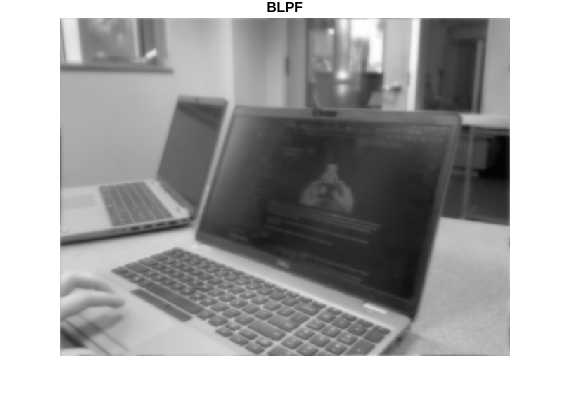

n=1; %Butterworth filter of order n
H= 1./(1 + (D./u0).^(2*n));
imshow(abs(fftshift(H)));
title('H(u,v) BLPF')

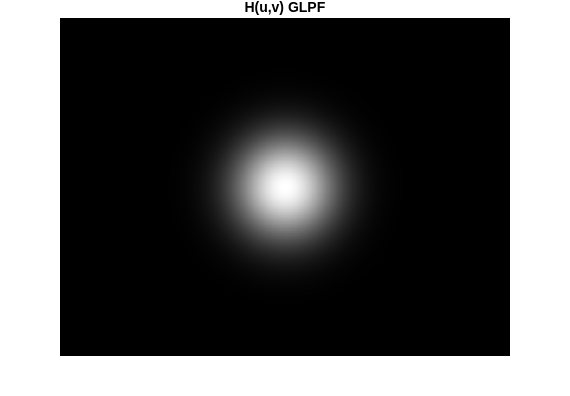

G=H.*F;
gbutter=(ifft2(G));
imshow(uint8(gbutter))
title('BLPF')

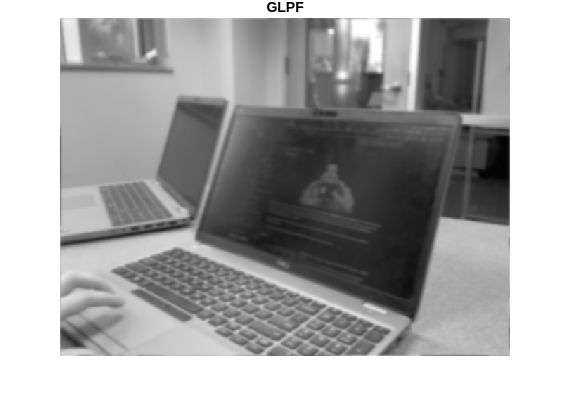

%% Gaussian low pass filter
H = exp(-(D.^2)./(2*(u0^2)));
imshow(abs(fftshift(H)));
title('H(u,v) GLPF')

G=H.*F;
ggauss=(ifft2(G));
imshow(uint8(ggauss))
title('GLPF')

The image resulting from the ideal LPF filter showed a lot of visible artifacts echoing away from edges, likely due to the sharp edge of the filter. 